per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 1

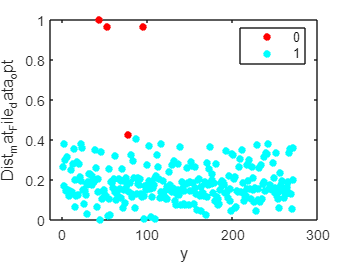

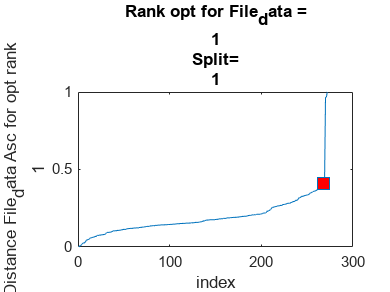

ind_O_File_data =     44    53    78    95


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 9

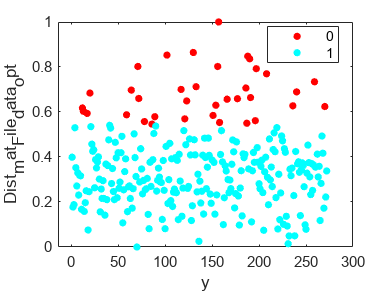

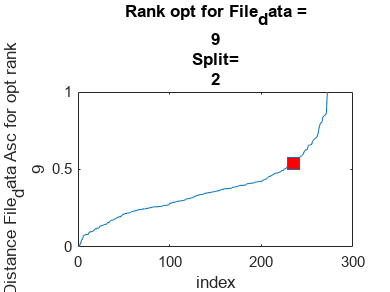

ind_O_File_data =     12    13    17    20    59    64    71    72    78    86    89   102   117   121   123   130   133   151   154   156   157   158   166   177   186   187   188   190   191   196   197   208   236   240   259   261   270


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 4

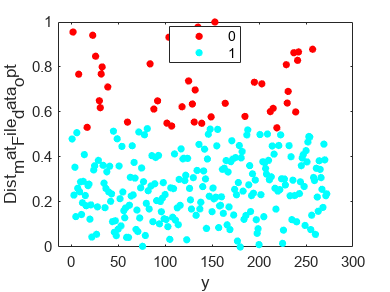

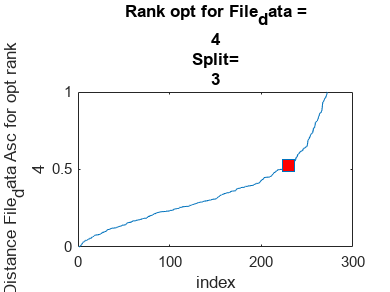

ind_O_File_data =      2     8    17    23    26    30    31    32    33    39    60    84    88    92   102   104   107   112   118   125   129   131   132   135   139   149   153   164   185   195   203   212   215   219   229   230   231   237   239   241   242   257


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 9

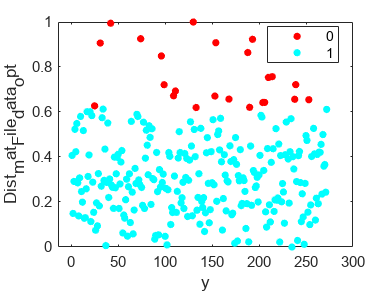

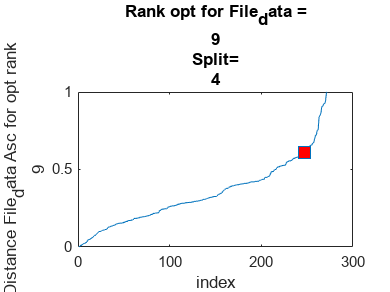

ind_O_File_data =     25    31    42    74    96    99   109   111   130   133   153   154   168   188   190   193   204   206   210   214   230   238   239   253   257


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 13

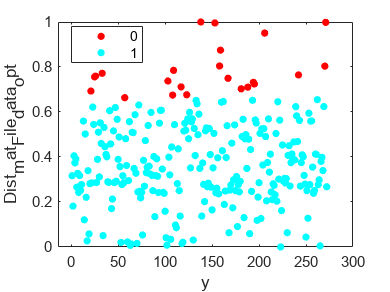

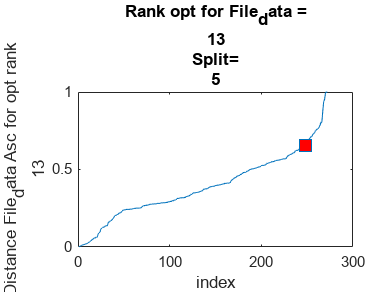

ind_O_File_data =     12    21    25    26    33    57   103   108   109   117   123   138   153   158   159   167   181   188   194   195   206   242   270   271


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 6

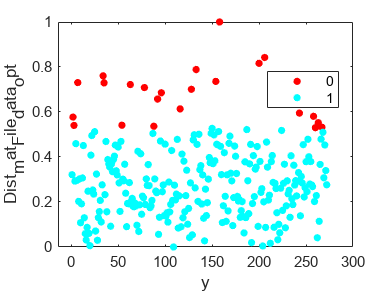

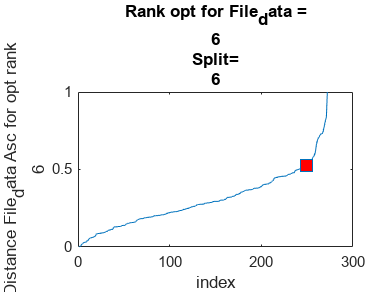

ind_O_File_data =      2     3     7    34    35    54    63    78    88    92    96   116   128   133   154   158   200   206   243   258   260   263   267


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 9

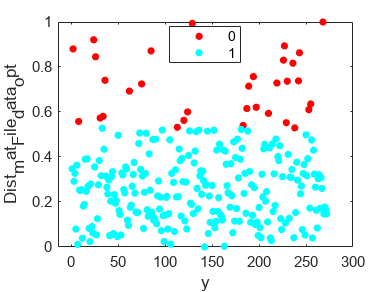

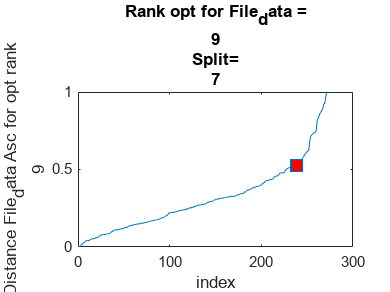

ind_O_File_data =      2     8    24    26    31    34    36    62    75    85   108   113   120   124   129   149   183   187   189   194   197   210   219   226   227   229   230   236   238   242   243   253   255   268


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 1

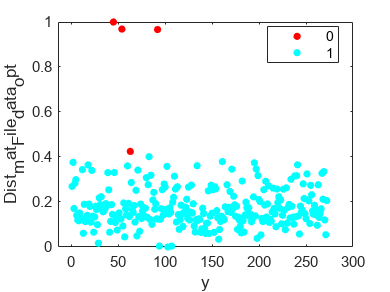

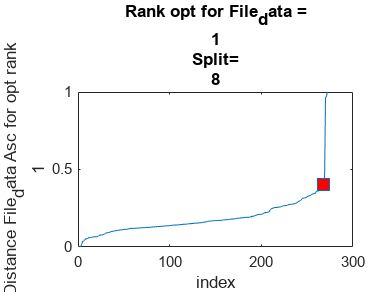

ind_O_File_data =     45    54    63    92


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 1

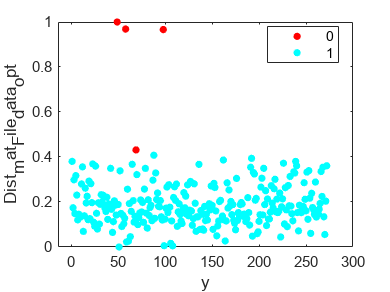

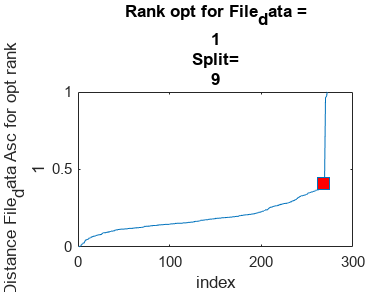

ind_O_File_data =     49    58    69    98


per = 0

Rank is 1 
Rank is 2 
Rank is 3 
Rank is 4 
Rank is 5 
Rank is 6 
Rank is 7 
Rank is 8 
Rank is 9 
Rank is 10 
Rank is 11 
Rank is 12 
Rank is 13 


optrank_File_data = 9

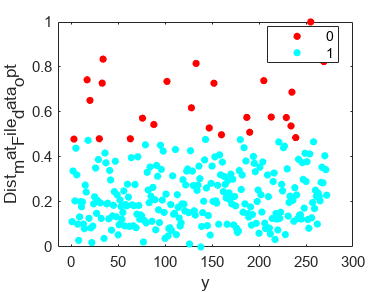

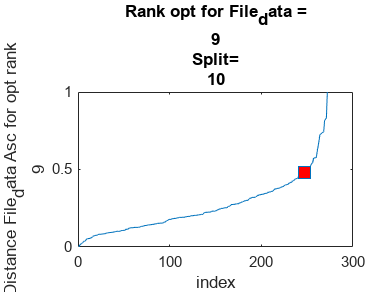

ind_O_File_data =      3    17    20    30    33    34    63    76    88   102   128   133   147   152   160   187   190   205   213   229   234   235   239   255   269


for j = [1,2,3,4,5,6,7,8,9,10]

    splitfolder=strcat('split',num2str(j));
    M=importdata("C:\Users\shukl\Documents\GitHub\sleep\split1\Sleep_Efficiency_train_set.csv",",",1);
    per =10%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\sleep\
        cd (splitfolder)

        fol= strcat('per',num2str(percent));
        cd (fol)

        my_file = strcat('Sleep_Efficiency_noisy_per_',num2str(percent),'.csv');
        
        File=readmatrix(my_file,"NumHeaderLines",1);
        %per_folder= strcat('per',num2str(per));

        File_data=File(:,1:14);
        %File_target=File(:,14);
        T_File_data=File_data.';
        %T_File_target=File_target.';
% 
%         Insm=File(File(:,11)==1,1:10);
%         T_Insm=Insm.';
%         T_Insm_org=Insm.';
% 
%         SA=File(File(:,11)==2,1:10);
%         T_SA=SA.';
%         T_SA_org=SA.';

        folder=strcat('ACE_dist_reg_optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder);
        cd (folder);

        ranks=[1,2,3,4,5,6,7,8,9,10,11,12,13];

        error_File_data = nan(size(ranks));
        numFile_data=length(T_File_data);
        Dist_mat_File_data_array_asc=nan(length(ranks),numFile_data);
        threshold_rank_File_data=nan(size(ranks));
        elbow_indx_rank_File_data=nan(size(ranks));


        for i = ranks
            fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\sleep\

            T_File_data_temp=T_File_data;
%            T_File_target_temp=T_File_target;
            Dist_mat_File_data=[];


            BF_File_data=l1pca_BF(T_File_data,i,1,10,10,'');
            for k = 1 : numFile_data
                A=T_File_data(:,k);
                Dist_mat_File_data(k)=norm((A-(BF_File_data*BF_File_data.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_File_data,[],"all");
            max_val=max(Dist_mat_File_data,[],"all");
            Dist_mat_File_data= Dist_mat_File_data-min_val;%]/[max_val-min_val]
            Dist_mat_File_data=Dist_mat_File_data /(max_val-min_val);


            Dist_mat_File_data_array_asc(i,:)=Dist_mat_File_data;
            [Dist_mat_File_data_asc,Indx_File_data]=sort(Dist_mat_File_data,"ascend");


            [elbow_File_data_err_angle,elbow_indx_File_data]=knee_pt_angle(Dist_mat_File_data_asc);

            error_File_data(i)=elbow_File_data_err_angle;
            threshold_rank_File_data(i)=Dist_mat_File_data_asc(elbow_indx_File_data);
            elbow_indx_rank_File_data(i)=elbow_indx_File_data;


%             figure
%             plot(Dist_mat_File_data_asc,'-p',"MarkerIndices",(elbow_indx_File_data),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance File_data Asc for rank", num2str(i)])
%             title(['Rank =',num2str(i) ])
% %             cd (splitfolder)
% %             cd (folder)
%             print(gcf,strcat('File_data',num2str(j),num2str(i),'.png'),'-dpng');

        end

        [~,optrank_File_data]= max(error_File_data)

        Dist_mat_File_data_opt=Dist_mat_File_data_array_asc(optrank_File_data,:);
        threshold_dist_File_data= threshold_rank_File_data(optrank_File_data);
        elbow_indx_File_data_opt=elbow_indx_rank_File_data(optrank_File_data);

        ind_O_File_data=find(Dist_mat_File_data_opt>threshold_dist_File_data);
        ind_I_File_data=find(Dist_mat_File_data_opt<=threshold_dist_File_data);


        cluster_File_data=zeros(size(Dist_mat_File_data_opt));
        cluster_File_data(ind_I_File_data)=1;
        figure
        y= 1:1:length(File_data);
        numGroups = length(unique(cluster_File_data));
        gscatter(y,Dist_mat_File_data_opt,cluster_File_data,hsv(numGroups))

        figure
        plot(sort(Dist_mat_File_data_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_File_data_opt),'MarkerFaceColor','red','MarkerSize',10 )
        xlabel("index")
        ylabel(["Distance File_data Asc for opt rank",num2str(optrank_File_data)])
        title(['Rank opt for File_data =',num2str(optrank_File_data),"Split=",num2str(j)])

        %print(gcf,strcat('Rank_Opt_File_data',num2str(j),'.png'),'-dpng');

        
        
        ind_O_File_data


        T_File_data_temp(:,ind_O_File_data)=[];
%        T_File_target_temp(:,ind_O_File_data)=[];
        length(T_File_data_temp);
        
        T_Filedata=T_File_data_temp.';
%        T_FileTarget=T_File_target_temp.';
        Final_File_data=T_Filedata;%[T_Filedata T_FileTarget] ;
%         Final_File_data(:,11)=0;

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% %         error_Insm = nan(size(ranks));
% %         numInsm=length(T_Insm);
% %         Dist_mat_Insm_array_asc=nan(length(ranks),numInsm);
% %         threshold_rank_Insm=nan(size(ranks));
% %         elbow_indx_rank_Insm=nan(size(ranks));
% % 
% %         for i = ranks
% %             %fprintf("Rank is %i \n", i) %i);
% %             cd C:\Users\shukl\Documents\GitHub\sleep\
% % 
% %             T_Insm_temp=T_Insm;
% %             Dist_mat_Insm=[];
% % 
% % 
% %             BF_Insm=l1pca_BF(T_Insm,i,1,10,10,'');
% %             for k = 1 : numInsm
% %                 A=T_Insm(:,k);
% %                 Dist_mat_Insm(k)=norm((A-(BF_Insm*BF_Insm.'*A)),1);
% %                 k;
% %             end
% % 
% %             min_val=min(Dist_mat_Insm,[],"all");
% %             max_val=max(Dist_mat_Insm,[],"all");
% %             Dist_mat_Insm= Dist_mat_Insm-min_val;%]/[max_val-min_val]
% %             Dist_mat_Insm=Dist_mat_Insm /(max_val-min_val);
% % 
% % 
% %             Dist_mat_Insm_array_asc(i,:)=Dist_mat_Insm;
% %             [Dist_mat_Insm_asc,Indx_Insm]=sort(Dist_mat_Insm,"ascend");
% % 
% % 
% %             [elbow_Insm_err,elbow_indx_Insm]=knee_pt_angle((Dist_mat_Insm_asc));
% % 
% %             error_Insm(i)=elbow_Insm_err;
% %             threshold_rank_Insm(i)=Dist_mat_Insm_asc(elbow_indx_Insm);
% %             elbow_indx_rank_Insm(i)=elbow_indx_Insm;
% % 
% % %             figure
% % %             plot(Dist_mat_Insm_asc,'-p',"MarkerIndices",(elbow_indx_Insm),'MarkerFaceColor','red','MarkerSize',10 )
% % %             xlabel("index")
% % %             ylabel(["Distance Insm Asc for rank", num2str(i)])
% % %             title(['Rank =',num2str(i) ])
% % % %             cd (splitfolder)
% % % %             cd (folder)
% % %             print(gcf,strcat('Insm',num2str(j),num2str(i),'.png'),'-dpng');
% % %             
% % 
% % 
% %         end
% % 
% %         [~,optrank_Insm]= max(error_Insm)
% % 
% %         Dist_mat_Insm_opt=Dist_mat_Insm_array_asc(optrank_Insm,:);
% %         threshold_dist_Insm= threshold_rank_Insm(optrank_Insm);
% %         elbow_indx_Insm_opt=elbow_indx_rank_Insm(optrank_Insm);
% % 
% %         ind_O_Insm=find(Dist_mat_Insm_opt>threshold_dist_Insm);
% %         ind_I_Insm=find(Dist_mat_Insm_opt<=threshold_dist_Insm);
% % 
% % 
% %         cluster_Insm=zeros(size(Dist_mat_Insm_opt));
% %         cluster_Insm(ind_I_Insm)=1;
% %         figure
% %         y= 1:1:length(Insm);
% %         numGroups = length(unique(cluster_Insm));
% %         gscatter(y,Dist_mat_Insm_opt,cluster_Insm,hsv(numGroups))
% % 
% %         figure
% %         plot(sort(Dist_mat_Insm_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_Insm_opt),'MarkerFaceColor','red','MarkerSize',10 )
% %         xlabel("index")
% %         ylabel(["Distance Insm Asc for opt rank",num2str(optrank_Insm)])
% %         title(['Rank opt for Insm =',num2str(optrank_Insm),"Split=",num2str(j)])
% % 
% %         %print(gcf,strcat('Rank_Opt_Insm',num2str(j),'.png'),'-dpng');
% % 
% %         ind_O_Insm;
% % 
% % 
% %         T_Insm_temp(:,ind_O_Insm)=[];
% %         length(T_Insm_temp);
% % 
% %         Final_Insm=T_Insm_temp';
% %         Final_Insm(:,11)=1;
% % 
% %         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % 
% %         error_SA = nan(size(ranks));
% %         numSA=length(T_SA);
% %         Dist_mat_SA_array_asc=nan(length(ranks),numSA);
% %         threshold_rank_SA=nan(size(ranks));
% %         elbow_indx_rank_SA=nan(size(ranks));
% % 
% %         for i = ranks
% %             %fprintf("Rank is %i \n", i) %i);
% %             cd C:\Users\shukl\Documents\GitHub\sleep\
% % 
% %             T_SA_temp=T_SA;
% %             Dist_mat_SA=[];
% % 
% % 
% %             BF_SA=l1pca_BF(T_SA,i,1,10,10,'');
% %             for k = 1 : numSA
% %                 A=T_SA(:,k);
% %                 Dist_mat_SA(k)=norm((A-(BF_SA*BF_SA.'*A)),1);
% %                 k;
% %             end
% % 
% %             min_val=min(Dist_mat_SA,[],"all");
% %             max_val=max(Dist_mat_SA,[],"all");
% %             Dist_mat_SA= Dist_mat_SA-min_val;%]/[max_val-min_val]
% %             Dist_mat_SA=Dist_mat_SA /(max_val-min_val);
% % 
% % 
% %             Dist_mat_SA_array_asc(i,:)=Dist_mat_SA;
% %             [Dist_mat_SA_asc,Indx_SA]=sort(Dist_mat_SA,"ascend");
% % 
% % 
% %             [elbow_SA_err,elbow_indx_SA]=knee_pt_angle((Dist_mat_SA_asc));
% % 
% %             error_SA(i)=elbow_SA_err;
% %             threshold_rank_SA(i)=Dist_mat_SA_asc(elbow_indx_SA);
% %             elbow_indx_rank_SA(i)=elbow_indx_SA;
% % 
% % %             figure
% % %             plot(Dist_mat_SA_asc,'-p',"MarkerIndices",(elbow_indx_SA),'MarkerFaceColor','red','MarkerSize',10 )
% % %             xlabel("index")
% % %             ylabel(["Distance SA Asc for rank", num2str(i)])
% % %             title(['Rank =',num2str(i) ])
% % % %             cd (splitfolder)
% % % %             cd (folder)
% % %             print(gcf,strcat('SA',num2str(j),'.png'),'-dpng');
% % 
% % 
% %         end
% % 
% %         [~,optrank_SA]= max(error_SA)
% % 
% %         Dist_mat_SA_opt=Dist_mat_SA_array_asc(optrank_SA,:);
% %         threshold_dist_SA= threshold_rank_SA(optrank_SA);
% %         elbow_indx_SA_opt=elbow_indx_rank_SA(optrank_SA);
% % 
% %         ind_O_SA=find(Dist_mat_SA_opt>threshold_dist_SA);
% %         ind_I_SA=find(Dist_mat_SA_opt<=threshold_dist_SA);
% % 
% % 
% %         cluster_SA=zeros(size(Dist_mat_SA_opt));
% %         cluster_SA(ind_I_SA)=1;
% %         figure
% %         y= 1:1:length(SA);
% %         numGroups = length(unique(cluster_SA));
% %         gscatter(y,Dist_mat_SA_opt,cluster_SA,hsv(numGroups))
% % 
% %         figure
% %         plot(sort(Dist_mat_SA_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_SA_opt),'MarkerFaceColor','red','MarkerSize',10 )
% %         xlabel("index")
% %         ylabel(["Distance SA Asc for opt rank",num2str(optrank_SA)])
% %         title(['Rank opt for SA =',num2str(optrank_SA),"Split=",num2str(j)])
% % 
% %        % print(gcf,strcat('Rank_Opt_SA',num2str(j),num2str(i),'.png'),'-dpng');
% % 
% % 
% %         ind_O_SA;
% % 
% % 
% %         T_SA_temp(:,ind_O_SA)=[];
% %         length(T_SA_temp);
% % 
% %         Final_SA=T_SA_temp';
% %         Final_SA(:,11)=2;

        cd C:\Users\shukl\Documents\GitHub\sleep
        %mkdir (splitfolder)
        cd (splitfolder)
        cd (fol)
        %mkdir (folder)
        cd (folder)

        L1pca_file=Final_File_data;%(horzcat(Final_None.',Final_Insm.',Final_SA.')).';
        L1pca_file = array2table(L1pca_file);
        L1pca_file.Properties.VariableNames(1:14)=M.colheaders;
        filel1pca_3=strcat('Sleep_Efficiency_noisy_per',num2str(percent),'_ACE_l1pca.csv');
       writetable(L1pca_file,filel1pca_3)

        cd ..\
    end
    cd ..\..\
end